# Compare inhibition tuning curve to spike tuning curve

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

us = {};
ds = {};

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
priorityOrder_2b = {'Extracellular'};
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Inhibition'};
mustHave_2b = {'_ff', 'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

upSpikesPD = [];
upInhibitionPD = [];
%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_inhibition, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_spikes, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    us(end + 1) = {struct_i.cellID};
    upSpikesPD(end+1) = mod(loc_spikes.Analysis_Results.PreferredDirection, 360);
    meanPositivePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_inhibition.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanPositivePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanPositivePeakByOrientation(leaf(j)) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(relevantEpochs));
    end
    [~, inhibitionVector] = calculateDSI([0:45:315], meanPositivePeakByOrientation);
    upInhibitionPD(end+1) = mod(inhibitionVector(1), 360);
end

%downs second
downSpikesPD = [];
downInhibitionPD = [];
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_inhibition, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_spikes, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    ds(end + 1) = {struct_i.cellID};
    downSpikesPD(end+1) = mod(loc_spikes.Analysis_Results.PreferredDirection, 360);
    meanPositivePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_inhibition.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanPositivePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanPositivePeakByOrientation(leaf(j)) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(relevantEpochs));
    end
    [~, inhibitionVector] = calculateDSI([0:45:315], meanPositivePeakByOrientation);
    downInhibitionPD(end+1) = mod(inhibitionVector(1), 360);
end


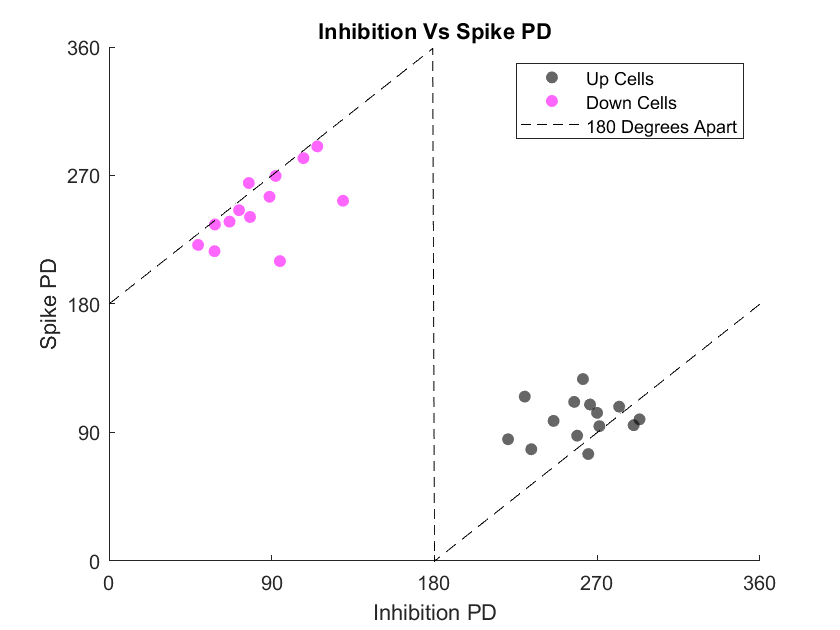

%show relationship between spike PD and inhibition PD
figure
title('Inhibition Vs Spike PD')
hold on
scatter(upInhibitionPD, upSpikesPD, 'k', 'filled', "MarkerFaceAlpha", 0.6)
scatter(downInhibitionPD, downSpikesPD, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlim([0, 360])
ylim([0, 360])
xlabel('Inhibition PD')
ylabel('Spike PD')
predicted = @(x) mod(x-180, 360);
outputPredicted = predicted([0:1:360]);
plot([0:1:360], outputPredicted, '--k')
legend({'Up Cells', 'Down Cells', '180 Degrees Apart'})
xticks([0:90:360])
yticks([0:90:360])
yticks([0:90:360])

## Clear the workspace and repeat for excitation

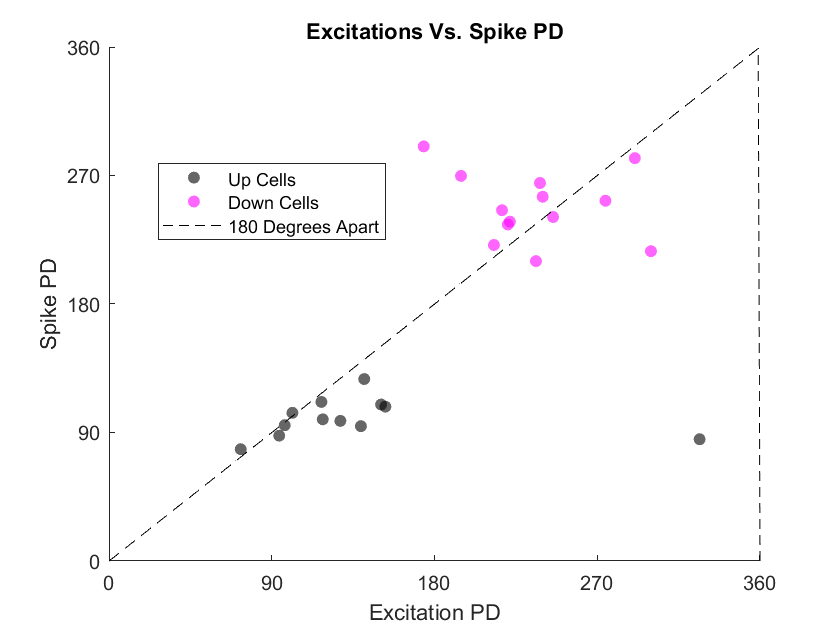


clearvars('-except', 'ups', 'downs','upInhibitionPD', 'downInhibitionPD')

us = {};
ds = {};

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
priorityOrder_2b = {'Extracellular'};
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Excitation'};
mustHave_2b = {'_ff', 'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

upSpikesPD = [];
upExcitationPD = [];
upExcitationPD_Peak = [];
upExcitationND_Peak = [];
upExcitationTCArea = [];
upSpikesTCArea = [];
upSpikesDSI = [];
upNormdTCArea = [];
%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_spikes, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    us(end + 1) = {struct_i.cellID};
    upSpikesPD(end+1) = mod(loc_spikes.Analysis_Results.PreferredDirection, 360);
    upSpikesDSI(end+1) = loc_spikes.Analysis_Results.DSI;
    meanSpikeResponse = loc_spikes.Analysis_Results.mean_spikesByOrientation;
    orientations_spikes = loc_spikes.Analysis_Results.Orientation;
    [~, leaf_spikes] = sort(orientations_spikes);
    spikes_sorted = meanSpikeResponse(leaf_spikes);
    upSpikesTCArea(end + 1) = trapz([0:45:360], [spikes_sorted, spikes_sorted(1)])/360;
    PDSpikeResponse = interp1([0:45:360], [spikes_sorted, spikes_sorted(1)], upSpikesPD(end));
    NormalizedSpikeCurve = spikes_sorted./PDSpikeResponse;
    upNormdTCArea(end+1) = trapz([0:45:360], [NormalizedSpikeCurve, NormalizedSpikeCurve(1)])/360;
    [~, closestPD_Index] = min(abs(PDSpikeResponse-[0:45:315]));
    closestPD = 45*(closestPD_Index-1);
    [~, minDirectionIndex] = min(meanSpikeResponse);
    minDirection = orientations_spikes(minDirectionIndex);
    
    
    meanNegativePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_excitation.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanNegativePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanNegativePeakByOrientation(leaf(j)) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
        if epochNumsByOrientation{j, 1} == closestPD
            upExcitationPD_Peak(end + 1) = -mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
        end
        if epochNumsByOrientation{j, 1} == minDirection
            upExcitationND_Peak(end + 1) = -mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
        end
    end
    [~, excitationVector] = calculateDSI([0:45:315], -meanNegativePeakByOrientation);
    upExcitationPD(end+1) = mod(excitationVector(1), 360);
    upExcitationTCArea(end+1) = trapz([0:45:360], [-meanNegativePeakByOrientation, -meanNegativePeakByOrientation(1)])/360;
end

%downs second
downSpikesPD = [];
downExcitationPD = [];
downExcitationPD_Peak = [];
downExcitationND_Peak = [];
downExcitationTCArea = [];
downSpikesTCArea = [];
downSpikesDSI = [];
downNormdTCArea = [];
downYs = [];
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_spikes, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    coords = struct_i.coordinates.polar;
    [x, y] = pol2cart(coords(1), coords(2));
    downYs(end + 1) = y;
    ds(end + 1) = {struct_i.cellID};
    downSpikesPD(end+1) = mod(loc_spikes.Analysis_Results.PreferredDirection, 360);
    downSpikesDSI(end+1) = loc_spikes.Analysis_Results.DSI;
    meanSpikeResponse = loc_spikes.Analysis_Results.mean_spikesByOrientation;
    orientations_spikes = loc_spikes.Analysis_Results.Orientation;
    [~, leaf_spikes] = sort(orientations_spikes);
    spikes_sorted = meanSpikeResponse(leaf_spikes);
    downSpikesTCArea(end + 1) = trapz([0:45:360], [spikes_sorted, spikes_sorted(1)])/360;
    PDSpikeResponse = interp1([0:45:360], [spikes_sorted, spikes_sorted(1)], downSpikesPD(end));
    NormalizedSpikeCurve = spikes_sorted./PDSpikeResponse;
    downNormdTCArea(end+1) = trapz([0:45:360], [NormalizedSpikeCurve, NormalizedSpikeCurve(1)])/360;
    [~, closestPD_Index] = min(abs(PDSpikeResponse-[0:45:315]));
    closestPD = 45*(closestPD_Index-1);
    [~, minDirectionIndex] = min(meanSpikeResponse);
    minDirection = orientations_spikes(minDirectionIndex);
    
    meanNegativePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_excitation.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanNegativePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanNegativePeakByOrientation(leaf(j)) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
        if epochNumsByOrientation{j, 1} == closestPD
            downExcitationPD_Peak(end + 1) = -mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
        end
        if epochNumsByOrientation{j, 1} == minDirection
            downExcitationND_Peak(end + 1) = -mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
        end
    end
    [~, excitationVector] = calculateDSI([0:45:315], -meanNegativePeakByOrientation);
    downExcitationPD(end+1) = mod(excitationVector(1), 360);
    downExcitationTCArea(end+1) = trapz([0:45:360], [-meanNegativePeakByOrientation, -meanNegativePeakByOrientation(1)])/360;
end

%show relationship between spike PD and excitation PD
figure
title('Excitations Vs. Spike PD')
hold on
scatter(upExcitationPD, upSpikesPD, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downExcitationPD, downSpikesPD, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlim([0, 360])
ylim([0, 360])
xlabel('Excitation PD')
ylabel('Spike PD')
predicted = @(x) mod(x, 360);
outputPredicted = predicted([0:1:360]);
plot([0:1:360], outputPredicted, '--k')
l = legend({'Up Cells', 'Down Cells', '180 Degrees Apart'});
l.Location = 'best';
xticks([0:90:360])
yticks([0:90:360])

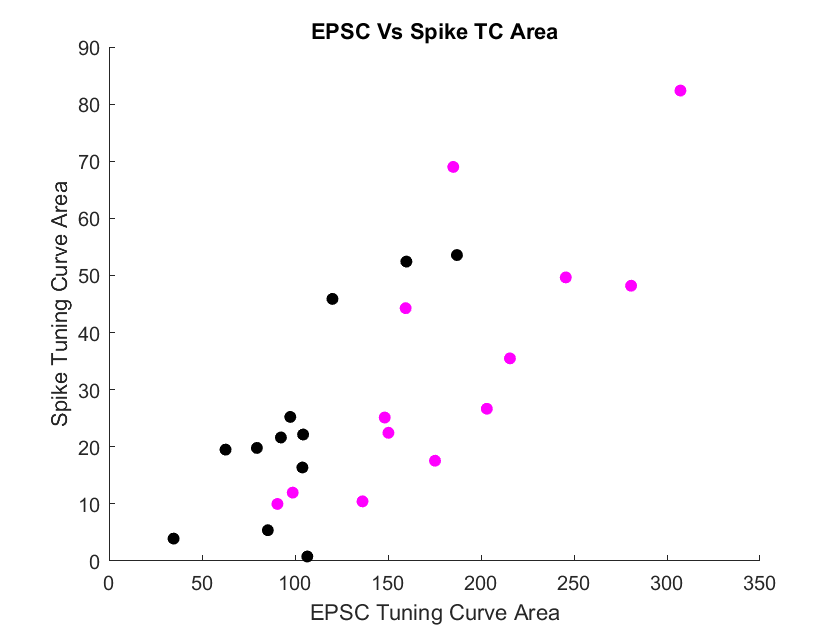

figure
title('EPSC Vs Spike TC Area')
hold on
scatter(upExcitationTCArea, upSpikesTCArea, 'k', 'filled')
scatter(downExcitationTCArea, downSpikesTCArea, 'm', 'filled')
ylabel('Spike Tuning Curve Area')
xlabel('EPSC Tuning Curve Area')

[r_up, p_up] = corr(upExcitationTCArea', upSpikesTCArea', 'type','Spearman')

r_up = 0.6294

p_up = 0.0324

[r_down, p_down] = corr(downExcitationTCArea', downSpikesTCArea', 'type', 'Pearson')

r_down = 0.7875

p_down = 0.0014

[r_total, p_total] = corr([upExcitationTCArea, downExcitationTCArea]', [upSpikesTCArea, downSpikesTCArea]', 'type','Spearman')

r_total = 0.7492

p_total = 2.6771e-05

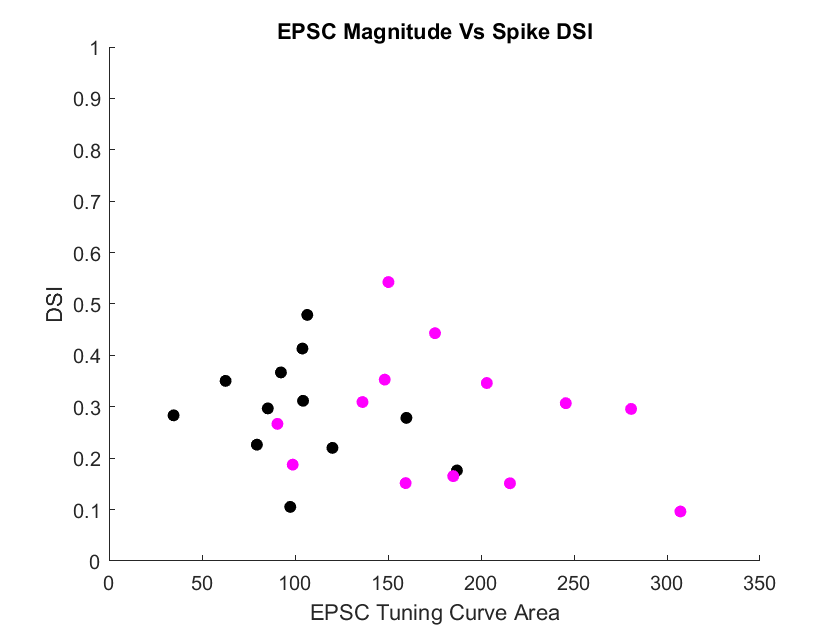

figure
title('EPSC Magnitude Vs Spike DSI')
hold on
scatter(upExcitationTCArea, upSpikesDSI, 'k', 'filled')
scatter(downExcitationTCArea, downSpikesDSI, 'm', 'filled')
ylabel('DSI')
xlabel('EPSC Tuning Curve Area')
ylim([0 1])


[r_up, p_up] = corr(upExcitationTCArea', upSpikesDSI', 'type','Spearman')

r_up = -0.2028

p_up = 0.5281

[r_down, p_down] = corr(downExcitationTCArea', downSpikesDSI', 'type', 'Pearson')

r_down = -0.2438

p_down = 0.4221

[r_total, p_total] = corr([upExcitationTCArea, downExcitationTCArea]', [upSpikesDSI, downSpikesDSI]', 'type','Spearman')

r_total = -0.1915

p_total = 0.3574

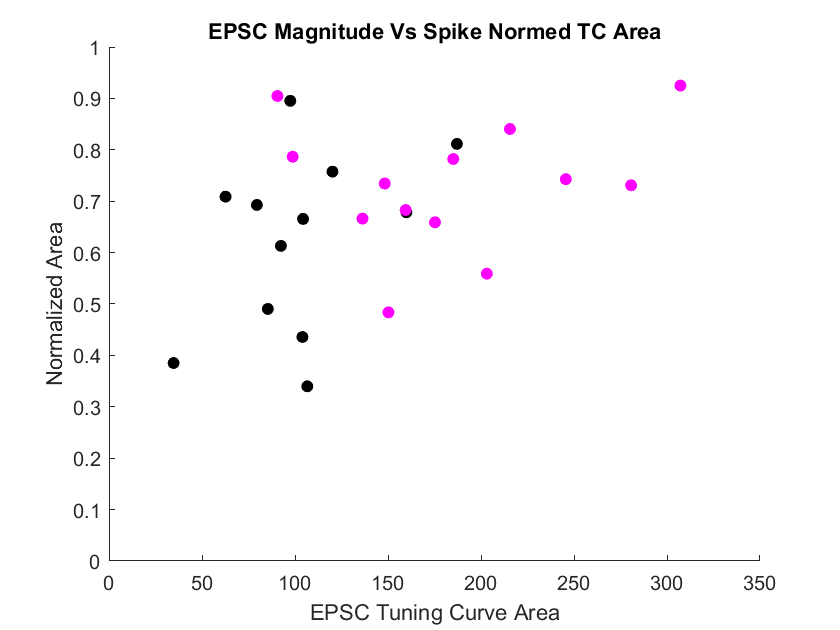

figure
title('EPSC Magnitude Vs Spike Normed TC Area')
hold on
scatter(upExcitationTCArea, upNormdTCArea, 'k', 'filled')
scatter(downExcitationTCArea, downNormdTCArea, 'm', 'filled')
ylabel('Normalized Area')
xlabel('EPSC Tuning Curve Area')
ylim([0 1])

[r_up, p_up] = corr(upExcitationTCArea', upNormdTCArea', 'type','Spearman')

r_up = 0.2587

p_up = 0.4169

[r_down, p_down] = corr(downExcitationTCArea', downNormdTCArea', 'type', 'Spearman')

r_down = 0.1099

p_down = 0.7232

[r_total, p_total] = corr([upExcitationTCArea, downExcitationTCArea]', [upNormdTCArea, downNormdTCArea]', 'type','Spearman')

r_total = 0.3038

p_total = 0.1397

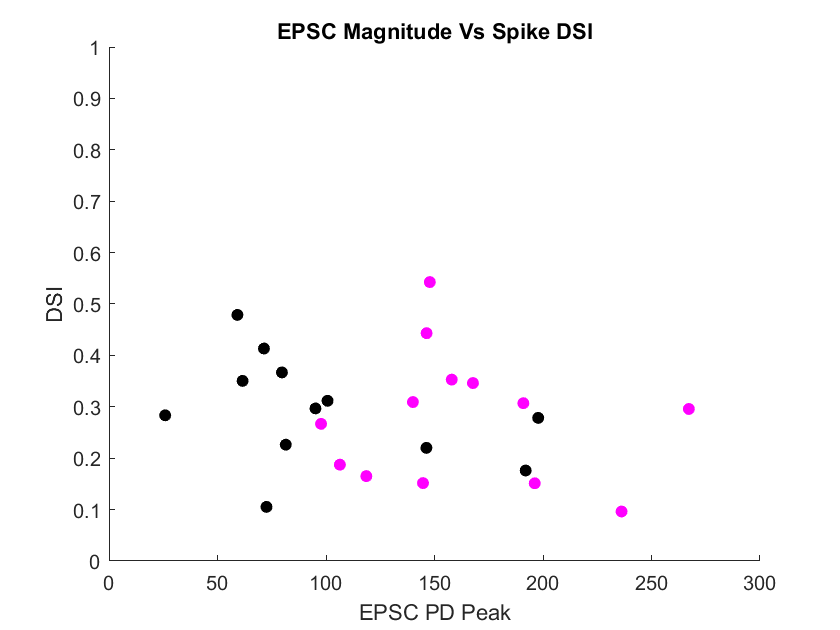

figure
title('EPSC Magnitude Vs Spike DSI')
hold on
scatter(upExcitationPD_Peak, upSpikesDSI, 'k', 'filled')
scatter(downExcitationPD_Peak, downSpikesDSI, 'm', 'filled')
ylabel('DSI')
xlabel('EPSC PD Peak')
ylim([0 1])

[r_up, p_up] = corr(upExcitationPD_Peak', upSpikesDSI', 'type','Spearman')

r_up = -0.5105

p_up = 0.0936

[r_down, p_down] = corr(downExcitationPD_Peak', downSpikesDSI', 'type', 'Pearson')

r_down = -0.1221

p_down = 0.6911

[r_total, p_total] = corr([upExcitationPD_Peak, downExcitationPD_Peak]', [upSpikesDSI, downSpikesDSI]', 'type','Spearman')

r_total = -0.2608

p_total = 0.2072

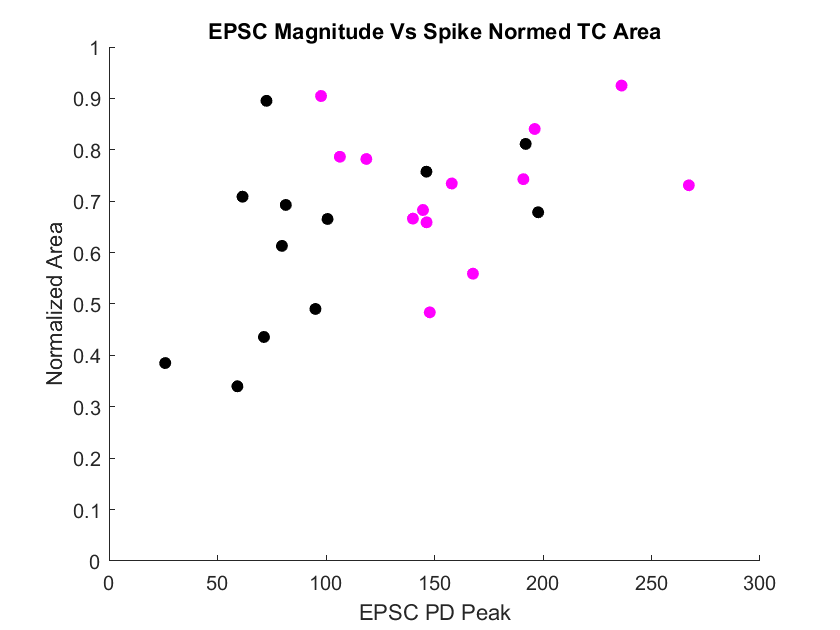

figure
title('EPSC Magnitude Vs Spike Normed TC Area')
hold on
scatter(upExcitationPD_Peak, upNormdTCArea, 'k', 'filled')
scatter(downExcitationPD_Peak, downNormdTCArea, 'm', 'filled')
ylabel('Normalized Area')
xlabel('EPSC PD Peak')
ylim([0 1])

[r_up, p_up] = corr(upExcitationPD_Peak', upNormdTCArea', 'type','Spearman')

r_up = 0.5105

p_up = 0.0936

[r_down, p_down] = corr(downExcitationPD_Peak', downNormdTCArea', 'type', 'Spearman')

r_down = -0.0165

p_down = 0.9639

[r_total, p_total] = corr([upExcitationPD_Peak, downExcitationPD_Peak]', [upNormdTCArea, downNormdTCArea]', 'type','Spearman')

r_total = 0.4108

p_total = 0.0424

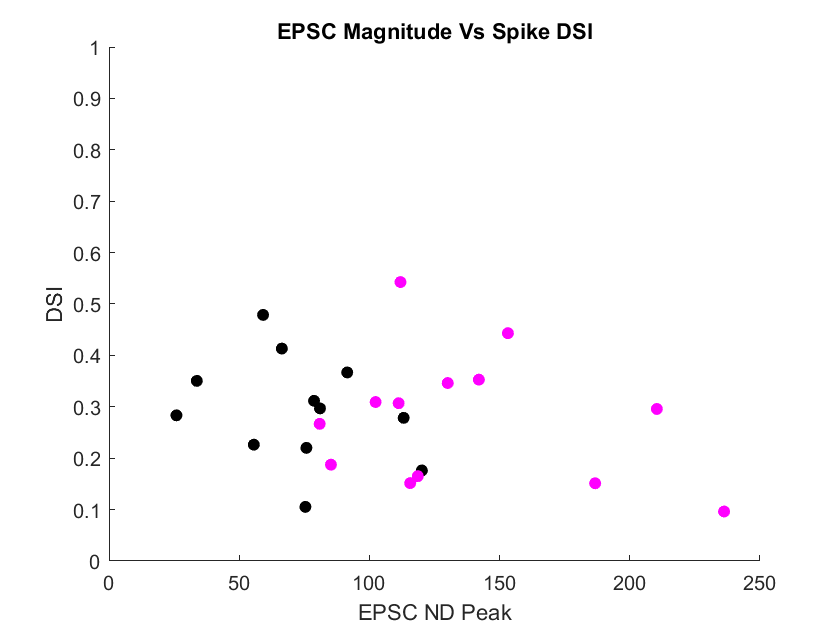

figure
title('EPSC Magnitude Vs Spike DSI')
hold on
scatter(upExcitationND_Peak, upSpikesDSI, 'k', 'filled')
scatter(downExcitationND_Peak, downSpikesDSI, 'm', 'filled')
ylabel('DSI')
xlabel('EPSC ND Peak')
ylim([0 1])

[r_up, p_up] = corr(upExcitationND_Peak', upSpikesDSI', 'type','Spearman')

r_up = -0.2448

p_up = 0.4435

[r_down, p_down] = corr(downExcitationND_Peak', downSpikesDSI', 'type', 'Pearson')

r_down = -0.2580

p_down = 0.3947

[r_total, p_total] = corr([upExcitationND_Peak, downExcitationND_Peak]', [upSpikesDSI, downSpikesDSI]', 'type','Spearman')

r_total = -0.1892

p_total = 0.3633

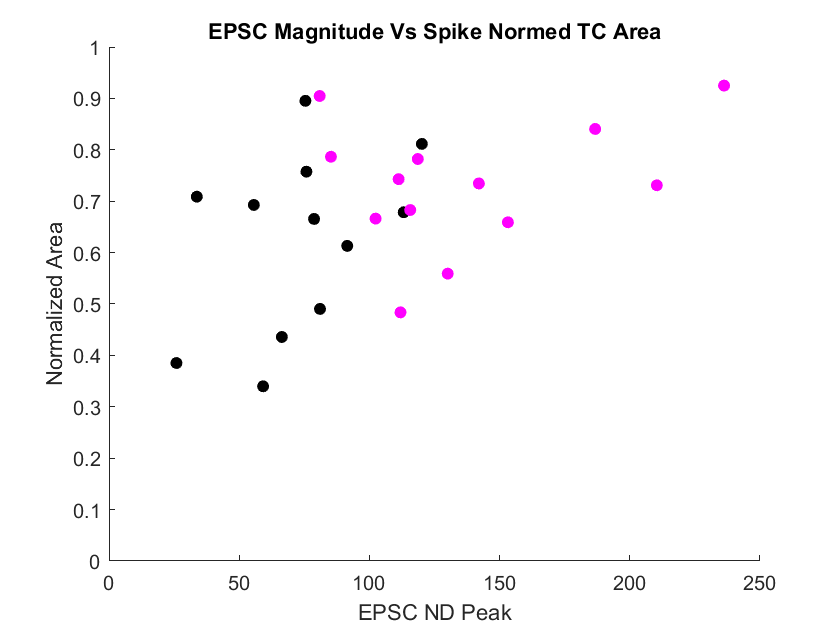

figure
title('EPSC Magnitude Vs Spike Normed TC Area')
hold on
scatter(upExcitationND_Peak, upNormdTCArea, 'k', 'filled')
scatter(downExcitationND_Peak, downNormdTCArea, 'm', 'filled')
ylabel('Normalized Area')
xlabel('EPSC ND Peak')
ylim([0 1])

[r_up, p_up] = corr(upExcitationND_Peak', upNormdTCArea', 'type','Spearman')

r_up = 0.2867

p_up = 0.3664

[r_down, p_down] = corr(downExcitationND_Peak', downNormdTCArea', 'type', 'Spearman')

r_down = 0.0440

p_down = 0.8918

[r_total, p_total] = corr([upExcitationND_Peak, downExcitationND_Peak]', [upNormdTCArea, downNormdTCArea]', 'type','Spearman')

r_total = 0.3392

p_total = 0.0976

## Repeat for excitation vs inhibition

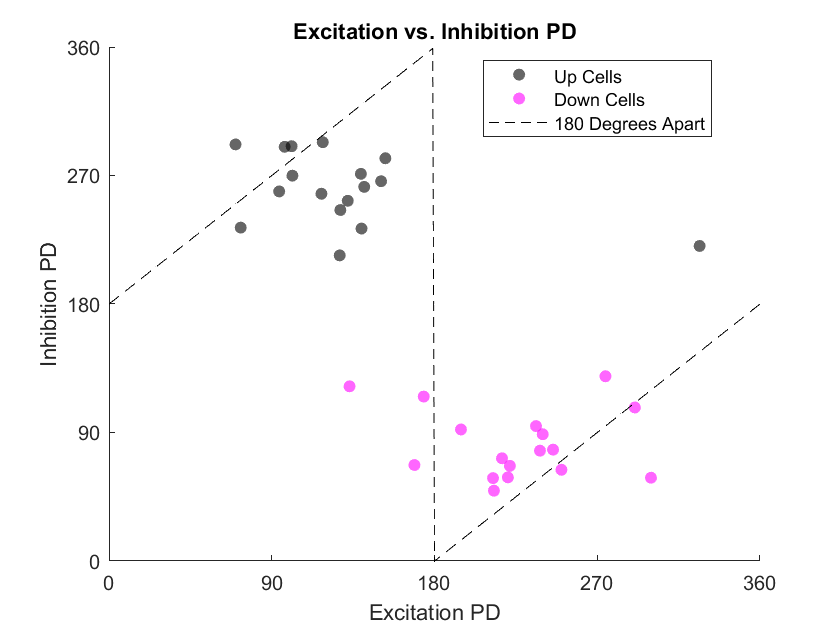

clearvars('-except', 'ups', 'downs')

us = {};
ds = {};

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Excitation'};
mustHave_2b = {'_ff', 'Intracellular', 'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

upInhibitionPD = [];
upExcitationPD = [];
%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    
    %excitation
    meanNegativePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_excitation.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanNegativePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanNegativePeakByOrientation(leaf(j)) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
    end
    [~, excitationVector] = calculateDSI([0:45:315], -meanNegativePeakByOrientation);
    upExcitationPD(end+1) = mod(excitationVector(1), 360);
    
    %excitation
    meanPositivePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_inhibition.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanPositivePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanPositivePeakByOrientation(leaf(j)) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(relevantEpochs));
    end
    [~, inhibitionVector] = calculateDSI([0:45:315], meanPositivePeakByOrientation);
    upInhibitionPD(end+1) = mod(inhibitionVector(1), 360);
end

downInhibitionPD = [];
downExcitationPD = [];
%downs first
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    
    %excitation
    meanNegativePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_excitation.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanNegativePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanNegativePeakByOrientation(leaf(j)) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(relevantEpochs));
    end
    [~, excitationVector] = calculateDSI([0:45:315], -meanNegativePeakByOrientation);
    downExcitationPD(end+1) = mod(excitationVector(1), 360);
    
    %excitation
    meanPositivePeakByOrientation = zeros(1, 8);
    epochNumsByOrientation = loc_inhibition.Analysis_Results.epochNumsByOrientation;
    [~, leaf] = sort(cell2mat(epochNumsByOrientation(:, 1)));
    for j = 1:size(meanPositivePeakByOrientation, 2)
        relevantEpochs = epochNumsByOrientation{j, 2};
        meanPositivePeakByOrientation(leaf(j)) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(relevantEpochs));
    end
    [~, inhibitionVector] = calculateDSI([0:45:315], meanPositivePeakByOrientation);
    downInhibitionPD(end+1) = mod(inhibitionVector(1), 360);
end


%show relationship between spike PD and excitation PD
figure
title('Excitation vs. Inhibition PD')
hold on
scatter(upExcitationPD, upInhibitionPD, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downExcitationPD, downInhibitionPD, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlim([0, 360])
ylim([0, 360])
xlabel('Excitation PD')
ylabel('Inhibition PD')
predicted = @(x) mod(x-180, 360);
outputPredicted = predicted([0:1:360]);
plot([0:1:360], outputPredicted, '--k')
l = legend({'Up Cells', 'Down Cells', '180 Degrees Apart'});
l.Location = 'best';
xticks([0:90:360])
yticks([0:90:360])